# 2-Dimensional $H_\infty$ Controller for Canted-Rotors Octocopter - WIP

clearvars; clc; % clean-up

## System equations

The equations of motion are defined as:

$\ddot{x} =  \frac{1}{m_\mathrm{UAV}} \big( \, (T + F_{zb}) \sin\theta + (T_{xb} + F_{xb})\cos\theta \, \big)$,

$\ddot{z} = \frac{1}{m_\mathrm{UAV}} \big( \, (T + F_{zb}) \cos\theta + (T_{xb} + F_{xb})\sin\theta \, \big) + g$,


$$\ddot{\theta} = \frac{1}{J_\mathrm{UAV}} ( M + M_\mathrm{aero} )$$


where $T$ and $T_{xb}$ represent the vertical and horizontal forces produced by the UAV's rotors. Likewise, $M$ represents the pitching moment applied by differencial rotor commands. These forces and moment are defined as

$T = - C_T \cos\zeta \sum_{i=1}^8 {\omega_i}^2$,

$T_{xb} = 2 C_T \sin\zeta ( {\omega_3}^2 - {\omega_2}^2 )$,


$$M = 2 C_T D_\mathrm{UAV} \cos\zeta \left( {\omega_1}^2 \sin 22.5^\circ + {\omega_2}^2 \cos 22.5^\circ - {\omega_3}^2 \cos 22.5^\circ -{\omega_4}^2 \sin 22.5^\circ \right)$$


where $C_T$ is the rotors' coeffcient of lift, $\zeta$ is the cant angle of the motors, $D_\mathrm{UAV}$ is the distance between opposite pairs of rotors, and $\omega_i$ is the rotational speed of rotor $i$. The rotor numbers are shown in Figure 1b.

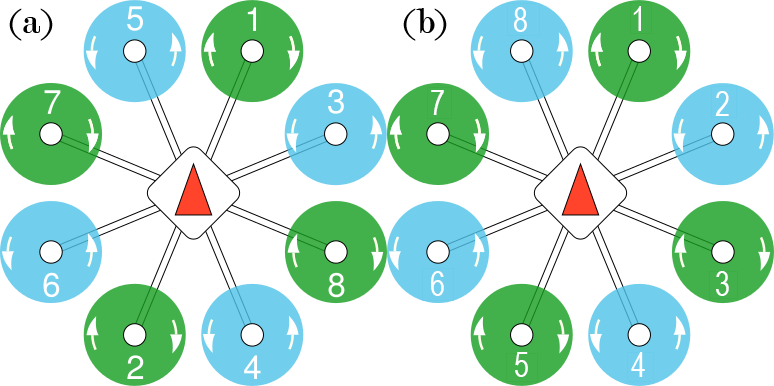

**Figure 1:** Rotor numbers (a) as seen by PX4 firmware, (b) used for modelling the system. **[Rotor directions might need to be inverted]**

The other forces acting on the UAV, $F_{zb}$ and $F_{xb}$, are vertical and horizontal aerodynamic forces. Likewise, $M_\mathrm{aero}$ is an aerodynamic pitching moment. These forces and moment are defined as

$F_{xb} = \frac{1}{2} \rho A_\mathrm{UAV} C_{xb,1} U^2 +  \frac{1}{2} \rho A_\mathrm{prop} D_\mathrm{prop} \frac{n}{4} C_{xb,2} U \bar{\omega}$,

$F_{zb} = \frac{1}{2} \rho A_\mathrm{UAV} C_{zb,1} U^2 +  \frac{1}{2} \rho A_\mathrm{prop} D_\mathrm{prop} \frac{n}{4} C_{zb,2} U \bar{\omega}$,


$$M_\mathrm{aero} = \frac{1}{2} \rho A_\mathrm{UAV} D_\mathrm{UAV} C_{M,1} U^2 +  \frac{1}{2} \rho A_\mathrm{prop} {D_\mathrm{prop}}^2 \frac{n}{4} C_{M,2} U \bar{\omega}$$


where $U$ is the effective wind speed acting on the UAV and $\bar{\omega}$ is the mean rotor speed. $n$ is the number of rotors, $\rho$ is the air density, $A_\mathrm{UAV}$ and $A_\mathrm{prop}$ are representative areas for the UAV and rotor respectively and $D_\mathrm{prop}$ is the diameter of a propeller. $C_{xb,1}$, $C_{xb,2}$, $C_{zb,1}$, $C_{zb,2}$, $C_{M,1}$, and $C_{M,2}$ are dimensionless aerodynamic coefficients defined as

$C_{xb,1} = -0.241\cos\alpha + 0.036\cos(3\alpha) + 0.016\cos(7\alpha)$,

$C_{xb,2} = -0.053\cos\alpha - 0.008\cos(3\alpha)$,

$C_{zb,1} = -0.724\sin\alpha + 0.080$,

$C_{zb,2} = -0.222\sin\alpha + 0.065$,

$C_{M,1} =  0.009\cos\alpha + 0.003\cos(3\alpha) - 0.014\sin(2\alpha)$,

$C_{M,2} =  A_1\cos\alpha + A_2\sin(2\alpha)$,

where $\alpha$ is the angle of attack of the wind. $A_1$ and $A_2$ are defined as

$A_1  =  0.116 ( 1 - e^{-0.126\lambda} )$,


$$A_2  = -0.041 ( 1 - e^{-0.308\lambda} )$$


where


$$\lambda = \frac{\bar{\omega} D_\mathrm{prop} }{ 2 U }$$


is the mean rotor tip-speed ratio.

## $H_\infty$ Controller Definition

Following the conventions highlighted in [1], the standard $H_\infty$ controller is shown in Figure 2.

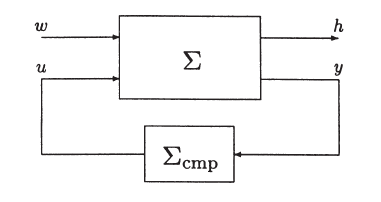

**Figure 2:** The standard $\mathcal{H}_\infty$-optimization problem. Retrieved from [1].

The plant and controller (compensator), $\Sigma$ and $\Sigma_\mathrm{cmp}$ respectively, are defined as


$$\Sigma :
\begin{cases}
\dot{\mathbf{x}} = \mathbf{A} \mathbf{x} + \mathbf{B}_1 \mathbf{\omega} + \mathbf{B}_2 \mathbf{u} \\
\mathbf{z} = \mathbf{C}_1 \mathbf{x} + \mathbf{D}_{12} \mathbf{u}\\
\mathbf{y} = \mathbf{C}_2 \mathbf{x} + \mathbf{D}_{21} \mathbf{\omega}
\end{cases} \enspace,$$



$$\Sigma_\mathrm{cmp} :
\begin{cases}
\dot{\mathbf{v}} = \mathbf{A}_\mathrm{cmp} \mathbf{v} + \mathbf{B}_\mathrm{cmp} \mathbf{y} \\
\mathbf{u} = \mathbf{C}_\mathrm{cmp} \mathbf{v} + \mathbf{D}_\mathrm{cmp} \mathbf{y}
\end{cases} \enspace.$$


where $\mathbf{x}$ is the state vector, $\mathbf{z}$ is the control output vector, $\mathbf{\omega}$ is noise input vector, and $\mathbf{u}$ is the input vector.

## Variable Choices for Controller

We first create the simplest controller possible. For the sake of this controller, we completely disregard the dynamics of the controller and motors. We assume we can directly control the mean rotor force $T_R$, the horizontal thrust, $T_{R,xy}$, and a pitching moment $M_R$ 

$\mathbf{u} = \left[\matrix{ T_R & T_{R,xy} & M_R} \right]^\top$ .

Next, we choose the state variables. As we disregarded all extraneous dynamics, we are left with two double integrators:

$\mathbf{x} = \left[\matrix{ \theta & \dot{\theta} & x & \dot{x} & z & \dot{z}}\right]^\top$.

The wind speed, $U$, is included in the disturbance vector. In addition, in order to be able to develop a standard $H_\infty$ controller, $\mathbf{D}_{21}$ must be full row rank. As a consequence, a measurement error $d_i$ state is added for each state.

$\mathbf{\omega} = \left[\matrix{ U & d_\theta & d_\dot{\theta} & d_x & d_z & d_\dot{x} & d_\dot{z}} \right]^\top$.

We include the position and velocity states in the regulated output vector since those are the states we want to regulate. In addition, in order to try to minimise the magnitude of the inputs, we include them in the regulated output. This also has the effect of meeting the requirement of $\mathbf{D}_{12}$ being full column rank.

$\mathbf{z} = \left[\matrix{ \mathbf{x} & \mathbf{u} }\right]^\top = \left[\matrix{ x & \dot{x} & z & \dot{z} & T_R & T_{R,xy} & M_R  }\right]^\top$.

From this, we can already define the $\mathbf{C}_1$ and $\mathbf{D}_{12}$ matrices as

$\mathbf{C}_1 =  \left[\matrix{ 0 & 0 & 1 & 0 & 0 & 0 \cr  0 & 0 & 0 & 1 & 0 & 0 \cr  0 & 0 & 0 & 0 & 1 & 0 \cr  0 & 0 & 0 & 0 & 0 & 1 \cr \mathbf{0} } \right], \mathbf{D}_{12} = \left[\matrix{ \mathbf{0} \cr \mathbf{I} } \right]$.

We assume that all states are measured.

$\mathbf{C}_2 = \mathbf{I}, \mathbf{D}_{21} = \left[\matrix{ \mathbf{0} & \mathbf{I} } \right]$.

## Linearisation of Simulink Model

We then use MATLAB to linearise our simplified simulink model to obtain the $\mathbf{A}$, $\mathbf{B}_1$, and $\mathbf{B}_2$ matrices.

LineariseOctocopter2D % Load parameters
mdl = 'Octocopter2DSimplified';
opspec = operspec(mdl);

We first trim the model. We do so around an arbitatry wind speed of 5 m/s.

% Configure the states for trimming
% Theta
opspec.States(1).SteadyState = 1;
opspec.States(1).Min = -deg2rad(45);
opspec.States(1).Max = deg2rad(45);
opspec.States(1).x   = 0;

% All the other states should be zero
for i = 2:6
    opspec.States(i).SteadyState = 1;
    opspec.States(i).Known = 1;
    opspec.States(i).x = 0;
end

% Inputs: there should be no horizontal thrust and the wind speed should be 5 m/s
opspec.Inputs(3).Known = 1;
opspec.Inputs(3).u = 0;
opspec.Inputs(4).Known = 1;
opspec.Inputs(4).u = 5;

% Set optimizer type - the default (gradient descent) does not work well in this case
opt = findopOptions('OptimizerType','simplex');
op = findop(mdl, opspec, opt)


 Operating point search report:
---------------------------------

 Operating point search report for the Model Octocopter2DSimplified.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) theta
      x:        -0.106      dx:             0 (0)
(2.) thetaDot
      x:             0      dx:      2.15e-06 (0)
(3.) x
      x:             0      dx:             0 (0)
(4.) z
      x:             0      dx:             0 (0)
(5.) xD


% Create vectors for use in simulation
for i = 1:length(op.States)
    x0(i) = op.States(i).x;
end

for i = 1:(length(op.Inputs)-1)
    u0(i) = op.Inputs(i).u;
end

We then use the operating point to linearise the system.

linsys = linearize(mdl,op)


linsys =
 
  A = 
                theta  thetaDot         x         z      xDot      zDot
   theta            0         1         0         0         0         0
   thetaDot        48         0         0         0     4.677     9.599
   x                0         0         0         0         1         0
   z                0         0         0         0         0         1
   xDot        -9.516         0         0         0   -0.3965    0.1035
   zDot        -8.594         0         0         0   -0.1563    -1.295
 
  B = 
                 Pitch     Thrust  HorThrust          U
   theta             0          0          0          0
   thetaDot      35.39      18.49     -33.83      4.677
   x                 0          0          0          0
   z                 0          0          0          0
   xDot        -0.6045    0.08758      1.358    -0.3965
   zDot       0.004887     -4.795    -0.1508    -0.1563
 
  C = 
            theta  thetaDot         x         z      xDot      zDot

We can take a look at some of the properties of the linearised system. For example,

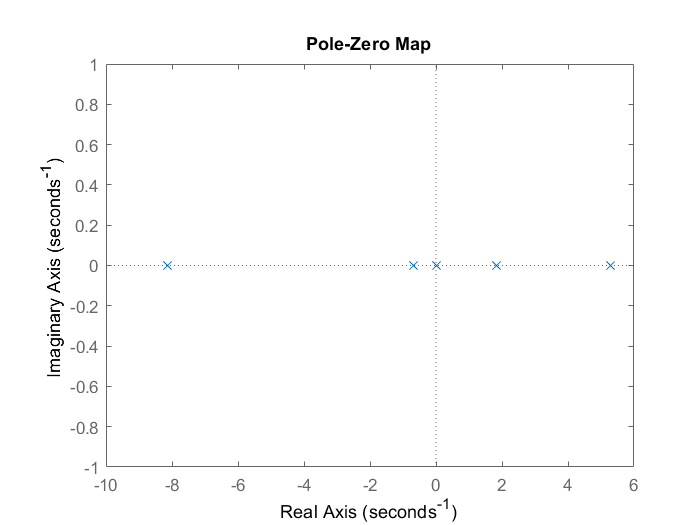

pzmap(linsys)

oltf = tf(linsys)


oltf =
 
  From input "Pitch" to output...
          -0.6045 s^3 - 0.7823 s^2 - 307.7 s - 480.3
   x:  ------------------------------------------------
       s^5 + 1.691 s^4 - 47.47 s^3 + 45.82 s^2 + 54.8 s
 
         0.004887 s^3 + 0.09641 s^2 - 304.3 s - 48.07
   z:  ------------------------------------------------
       s^5 + 1.691 s^4 - 47.47 s^3 + 45.82 s^2 + 54.8 s
 
           -0.6045 s^3 - 0.7823 s^2 - 307.7 s - 480.3
   xDot:  --------------------------------------------
          s^4 + 1.691 s^3 - 47.47 s^2 + 45.82 s + 54.8
 
          0.004887 s^3 + 0.09641 s^2 - 304.3 s - 48.07
   zDot:  --------------------------------------------
          s^4 + 1.691 s^3 - 47.47 s^2 + 45.82 s + 54.8
 
  From input "Thrust" to output...
          0.08758 s^3 - 0.3827 s^2 - 180.2 s + 219.3
   x:  ------------------------------------------------
       s^5 + 1.691 s^4 - 47.47 s^3 + 45.82 s^2 + 54.8 s
 
           -4.795 s^3 - 1.915 s^2 + 71.22 s - 160.5
   z:  ---------------------------

## Conversion of Linear Model to Standard $H_\infty$ State-Space Form

Those matrices are then split to fit the standard $H_\infty$ form.

Collecting theses equations we obtain the system equation in a parallel matrix notation as


$$\mathbf{P}_\Sigma = \left[ \matrix{
\mathbf{A} & \mathbf{B}_1 & \mathbf{B}_2 \cr
\mathbf{C}_1 & \mathbf{0} & \mathbf{D}_{12} \cr
\mathbf{C}_2 & \mathbf{D}_{21} & \mathbf{0}
} \right]$$


% Check requirements for Hinf control
nmeas = 6;
ncon  = 3;

% Get matrices
A = linsys.A;
B2 = linsys.B(:,1:ncon);
B1 = [linsys.B(:,ncon+1:end),zeros(size(A,1))];

C1 = [linsys.C; zeros(size(B2,2),size(linsys.C,2))];
D12 = [zeros(size(linsys.C,1), size(B2,2)); eye(size(B2,2))];

C2 = eye(length(A));
D21 = [zeros(size(C2,1),1), eye(size(C2,1))];

% The following checks are necessary for the method presented in ELECTENG704 but not necessarily
% hinfsyn - need further investigation
% (A,B1,C1) needs to be controllable and observable
unCtrlStates = length(A) - rank( ctrb(A,B1) )

unCtrlStates = 1

unObsvStates = length(A) - rank( obsv(A,C1) )

unObsvStates = 0


% (A,B1,C1) needs to stabilisable and detectability
G = ss(A,B2,C2,zeros(size(C2,1),size(B2,2)));
[GS,GNS] = stabsep(G); % Split into stable and unstable parts
unDtctStates = length(GNS.A) - rank(obsv(GNS))

unDtctStates = 0

unObsvStates = length(A) - rank( obsv(A,C2) ) % Temporary, observable implies detectable

unObsvStates = 0


% Pack the matrices
BPack = [ B1 B2 ];
CPack = [ C1; C2 ];
DPack = [ zeros(size(C1,1),size(B1,2)) D12; D21 zeros(size(C2,1),size(B2,2)) ];
Psig = pck( A, BPack, CPack, DPack );

gmin = 0.1; gmax = 55; tol = 1e-9;
[ K, CLS, gsyn ] = hinfsyn( Psig, nmeas, ncon, gmin, gmax, tol );

Test bounds:      0.1000 <  gamma  <=     55.0000

  gamma    hamx_eig  xinf_eig  hamy_eig   yinf_eig   nrho_xy   p/f
   55.000   9.8e-01   7.3e-02   2.8e-08    1.9e-10    0.0011    p 
   27.550   9.8e-01   7.3e-02   2.4e-08    1.7e-10    0.0045    p 
   13.825   9.8e-01   7.3e-02   9.1e-09    6.3e-11    0.0179    p 
    6.963   9.8e-01   7.3e-02   2.9e-17 #  *******    ******    f 
   10.394   9.8e-01   7.3e-02   2.2e-08    1.5e-10    0.0317    p 
    8.678   9.8e-01   7.3e-02   1.5e-16 #  *******    ******    f 
    9.536   9.8e-01   7.3e-02   1.7e-08    1.2e-10    0.0378    p 
    9.107   9.8e-01   7.3e-02   1.1e-16 #  *******    ******    f 
    9.321   9.8e-01   7.3e-02   1.0e-08    7.1e-11    0.0395    p 
    9.214   9.8e-01   7.3e-02   2.1e-08    1.5e-10    0.0405    p 
    9.161   9.8e-01   7.3e-02   4.9e-16 #  *******    ******    f 
    9.187   9.8e-01   7.3e-02   3.4e-16 #  *******    ******    f 
    9.201   9.8e-01   7.3e-02   3.4e-16 #  *******    ******    f 
    9.208  

[ACmp,BCmp,CCmp,DCmp] = unpck(K)

ACmp =    -0.3268   -0.6078    0.0868    0.0778    0.5619    0.4340
 -162.4620  -30.0684   53.0890   14.8702   64.2126   20.5859
    0.0879   -0.2812   -0.7982   -0.3118    0.2038   -0.3721
    0.0787   -0.1858   -0.3118   -0.2135   -0.5987    0.6771
   -3.9439    1.8433   -2.3263   -0.3807   -4.2159   -0.8998
   -0.7439    1.7953   -0.9117   -5.1722   -1.8516   -6.7896


BCmp =     0.0340    0.1673   -0.0091   -0.0082   -0.0592   -0.0457
    0.1673    1.1946    0.0293    0.0193   -0.1439   -0.1363
   -0.0091    0.0293    0.0840    0.0328    0.0838    0.0392
   -0.0082    0.0193    0.0328    0.0225    0.0630    0.0340
   -0.0592   -0.1439    0.0838    0.0630    0.2229    0.1396
   -0.0457   -0.1363    0.0392    0.0340    0.1396    0.0958


CCmp =   -23.8581   -2.3063    5.8385   -0.1729    6.3983   -0.9214
  -15.6914   -1.0480    1.3494    9.6941    1.0383    9.1497
   25.8071    2.2956   -8.3184    0.8411   -9.2673    1.2839


DCmp =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


## Response of Linear System

Figure 3 shows a Simulink model of the linearised controller. We set the all the initial conditions to 0 apart from the initial $x$ position to 1.

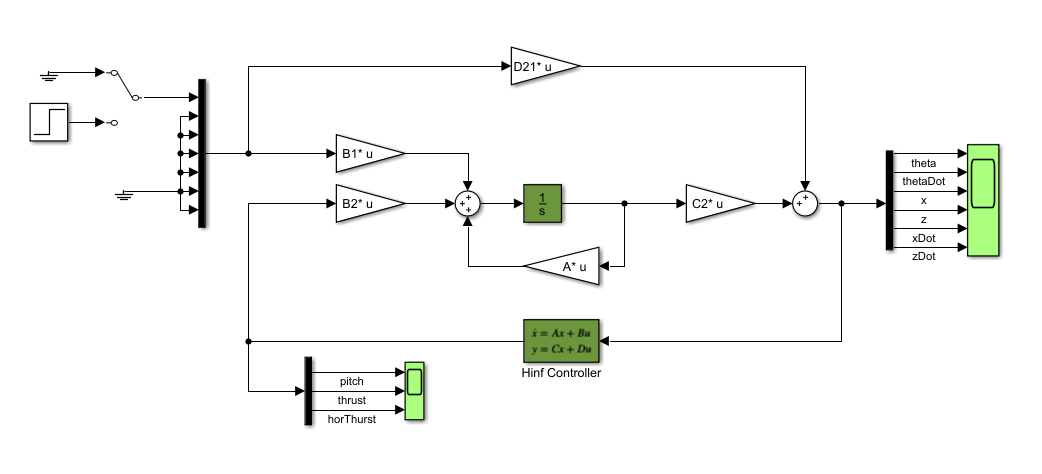

**Figure 3:** Simulink model of linearised system and $H_\infty$ controller

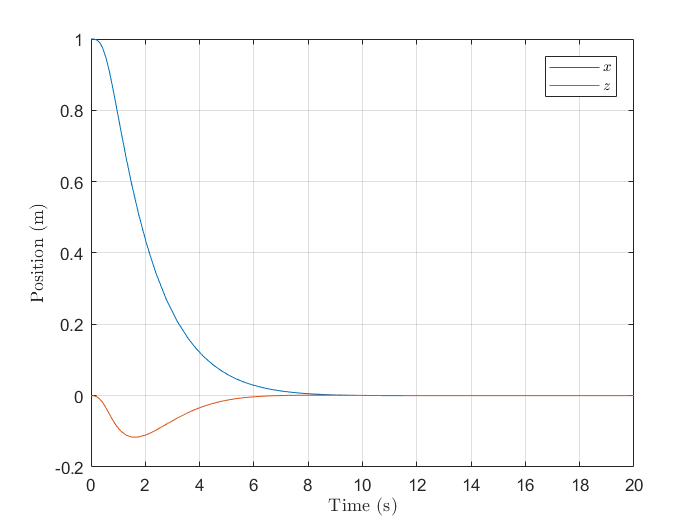

mdlLin = 'Octocopter2DLin';
output = sim( mdlLin, 'SimulationMode', 'normal');

figure
plot(output.tout, output.y(:,3),output.tout,output.y(:,4))
grid on; hold on;
xlabel('Time (s)','Interpreter','latex'); ylabel('Position (m)','Interpreter','latex')
legend({'$x$','$z$'},'Interpreter','latex')

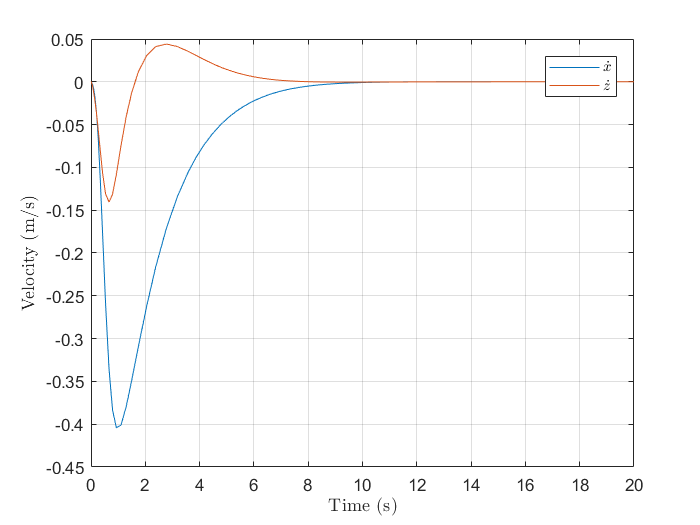


figure
plot(output.tout, output.y(:,5),output.tout,output.y(:,6))
grid on; hold on;
xlabel('Time (s)','Interpreter','latex'); ylabel('Velocity (m/s)','Interpreter','latex')
legend({'$\dot{x}$','$\dot{z}$'},'Interpreter','latex')

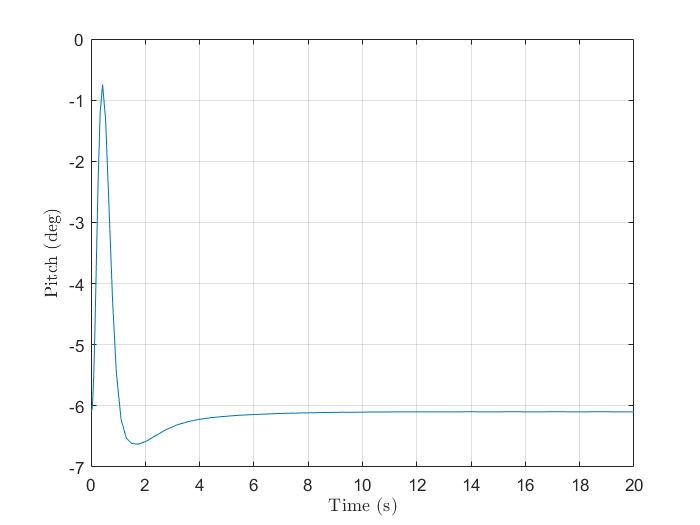


figure
plot(output.tout, rad2deg(output.y(:,1) + x0(1)) )
grid on; hold on;
xlabel('Time (s)','Interpreter','latex'); ylabel('Pitch (deg)','Interpreter','latex')

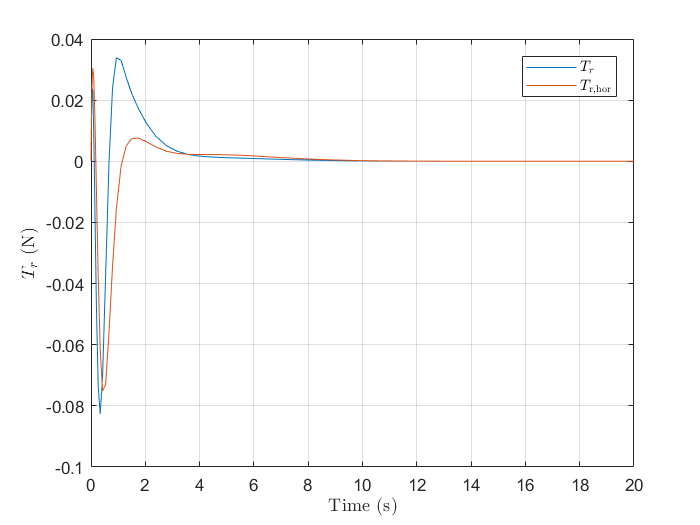


figure
plot(output.tout, output.u(:,1),output.tout,output.u(:,2))
grid on; hold on;
xlabel('Time (s)','Interpreter','latex'); ylabel('$T_r$ (N)','Interpreter','latex')
legend({'$T_r$','$T_\mathrm{r,hor}$'},'Interpreter','latex')

## References

- Chen, B. M. $\mathcal{H}_\infty$ Control and Its Applications. *Springer, ***1998***, 235*